## setup paths

addpath(strcat(pwd,'/src/'))
addpath(strcat(pwd,'/data/'))
addpath(genpath(strcat(pwd,'/src/external/')))

## get data

surf = load([pwd '/data/fsaverage/mat/' 'fsaverage_inflated.mat']) ;
surfStruct = surf.surfStruct ;

annots = load([pwd '/data/fsaverage/mat/' 'fsaverage_annots.mat']) ;
annotMap = annots.allAnnots ;

## plot some data

ans = struct with fields:
      border: 1
        cMap: [100×3 double]
      newFig: 1
    valRange: []
    viewcMap: 0
     viewStr: 'all'


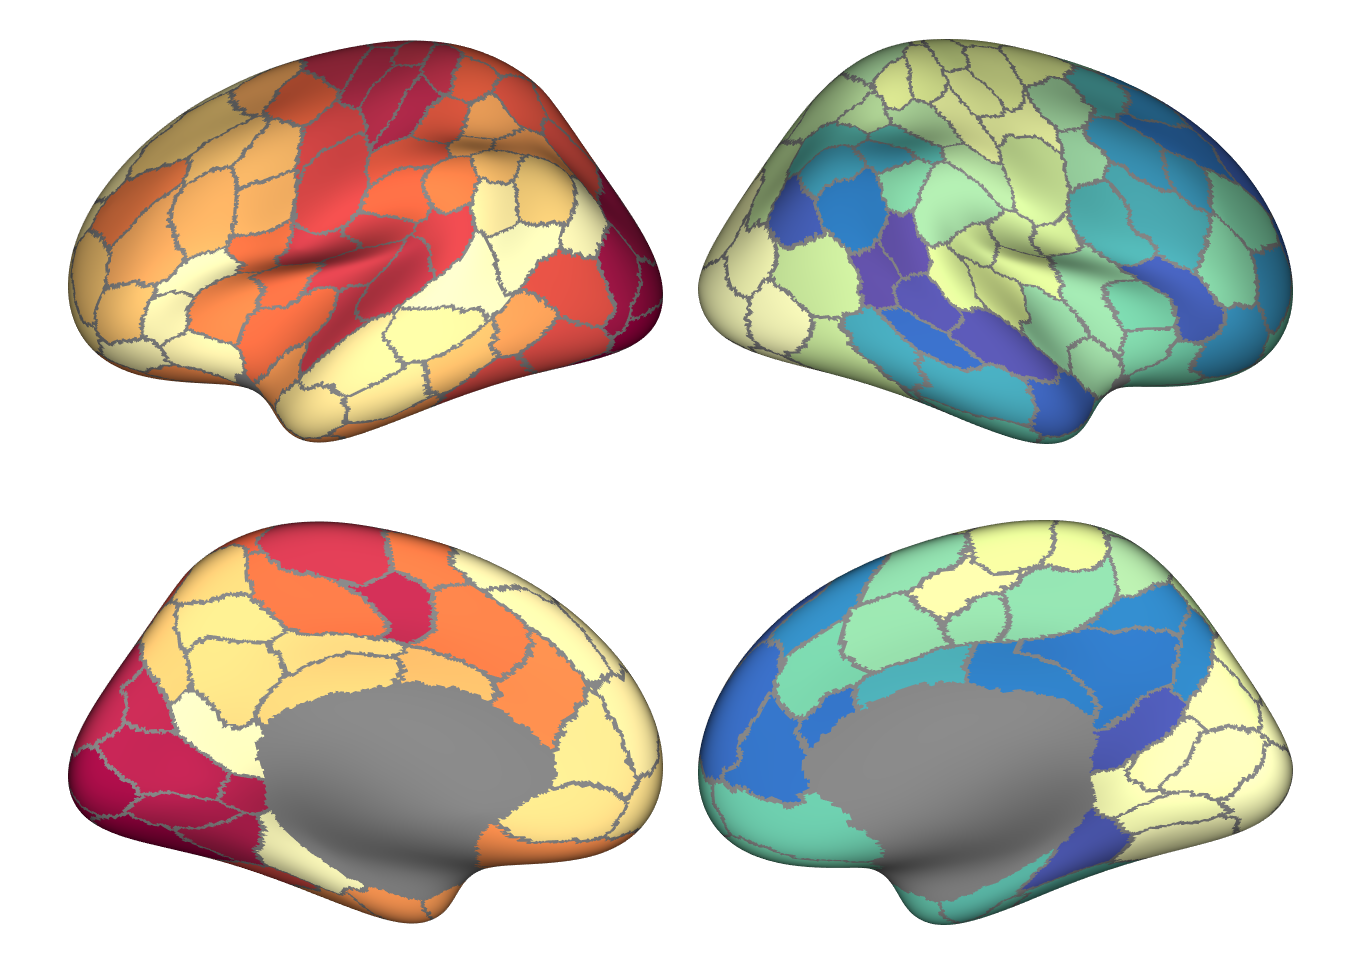

ans = 4×1 cell array
    {1×1 Patch}
    {1×1 Patch}
    {1×1 Patch}
    {1×1 Patch}


annotName = 'schaefer200-yeo17' ;

%dataVec = rand(200,1) ;
dataVec = -150:49 ;

parc_plot(surfStruct,annotMap,annotName,dataVec,...
    'viewcMap',0)

ans = struct with fields:
      border: 1
        cMap: [100×3 double]
      newFig: 0
    valRange: [-101 200]
    viewcMap: 0
     viewStr: 'lh:lat'


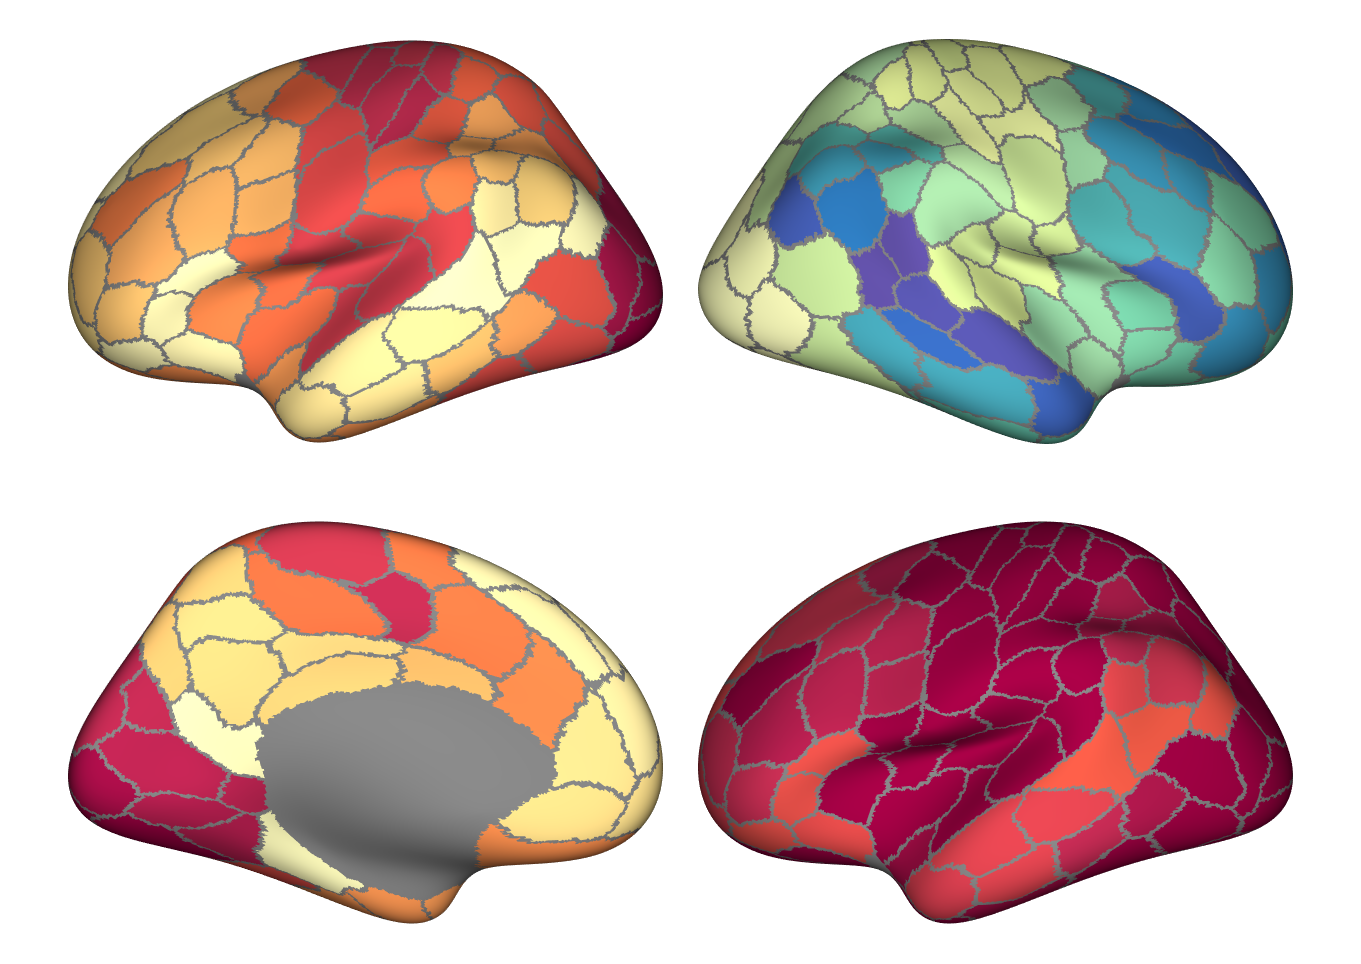

ans = 1×1 cell array
    {1×1 Patch}



parc_plot(surfStruct,annotMap,annotName,dataVec,...
    'Valrange', [-101 200],'viewcMap',0,'newFig',0,'viewStr','lh:lat')


% for your real data, you can check the order that is expected by the function by running:
% annotMap(annotName).combo_names
% this will show you should provide

## plot some data with a cmap

ans = struct with fields:
      border: 1
        cMap: [15×3 double]
      newFig: 1
    valRange: []
    viewcMap: []
     viewStr: 'all'


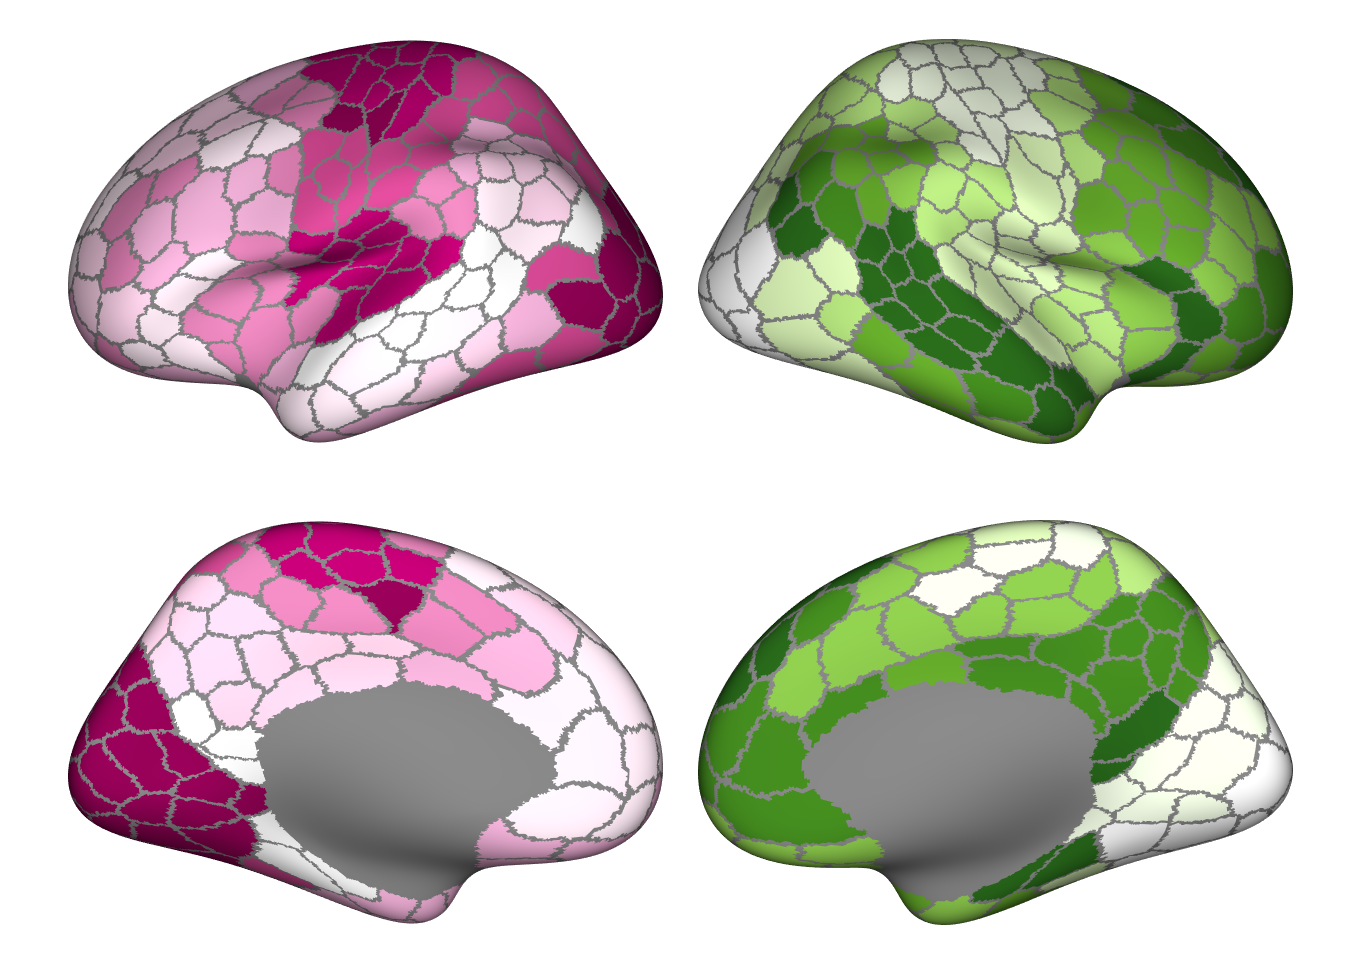

ans = 4×1 cell array
    {1×1 Patch}
    {1×1 Patch}
    {1×1 Patch}
    {1×1 Patch}


annotName = 'schaefer400-yeo17' ;

dataVec = 1:400 ;

parc_plot(surfStruct,annotMap,annotName,dataVec,...
    'cMap',brewermap(15,'PiYG'))

## plot the parc plot

ans = struct with fields:
      border: 0
        cMap: [200×3 double]
      newFig: 1
    valRange: []
    viewcMap: []
     viewStr: 'all'


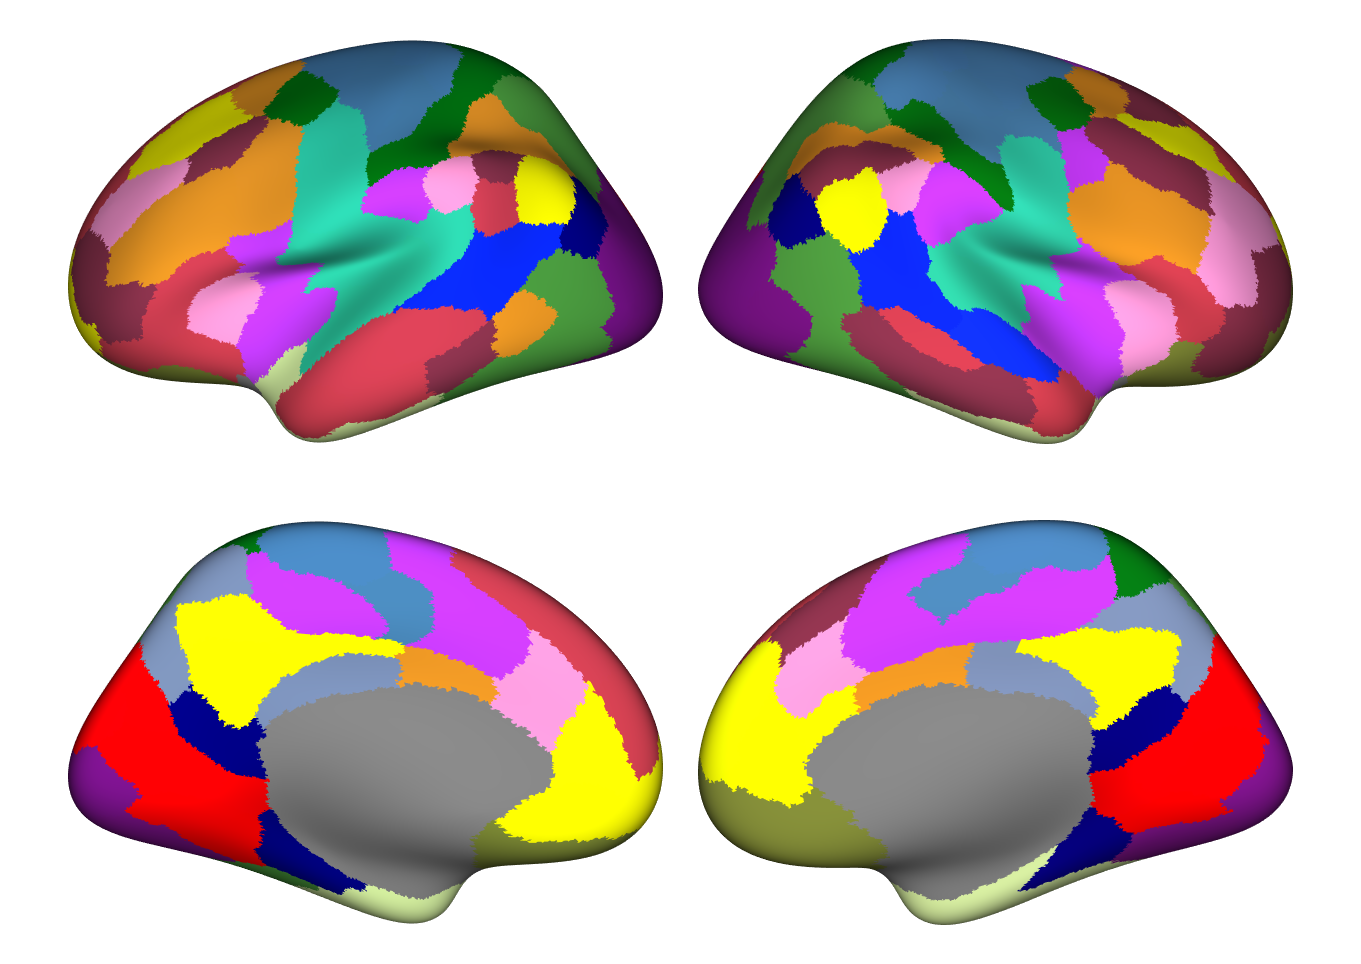

ans = 4×1 cell array
    {1×1 Patch}
    {1×1 Patch}
    {1×1 Patch}
    {1×1 Patch}


annotName = 'schaefer200-yeo17' ;

cmap = annotMap(annotName).combo_table(:,1:3) ./ 255 ;

% addParameter(p,'cMap',[ 0.5 0.5 0.5 ; brewermap(100,'Spectral') ])
% addParameter(p,'border',1)
% addParameter(p,'valrange',[])
% addParameter(p,'viewStr','all')
% addParameter(p,'viewcMap',[])
% parse(p, varargin{:})

% function [h] = parc_plot(surfStruct,annotMap,annotName,dataVec,cMap,viewStr)
parc_plot(surfStruct,annotMap,annotName,1:(size(cmap,1)),...
    'cMap',cmap, 'border',0)